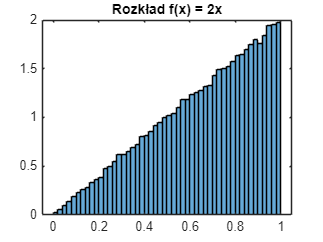

% Liczba losowych próbek
N = 100000;

% Zadanie 1: Generator dla f(x) = 2x, x ∈ [0,1]
U = rand(1, N);
X1 = sqrt(U);
figure(1);
histogram(X1, 50, 'Normalization', 'pdf');
title('Rozkład f(x) = 2x');

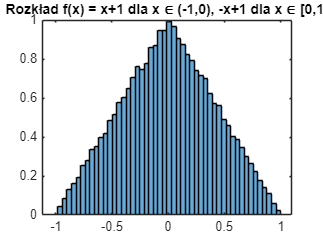


% Zadanie 2: Generator dla f(x) = x+1 dla x ∈ (-1,0), -x+1 dla x ∈ [0,1)
U = rand(1, N);
X2 = zeros(1, N);
X2(U < 0.5) = sqrt(2*U(U < 0.5)) - 1;
X2(U >= 0.5) = 1 - sqrt(2*(1 - U(U >= 0.5)));
figure(2);
histogram(X2, 50, 'Normalization', 'pdf');
title('Rozkład f(x) = x+1 dla x ∈ (-1,0), -x+1 dla x ∈ [0,1)');

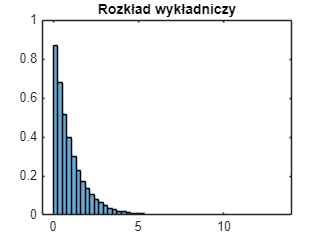


% Zadanie 3: Generator dla rozkładu wykładniczego f(x) = e^{-x}
U = rand(1, N);
X3 = -log(1 - U);
figure(3);
histogram(X3, 50, 'Normalization', 'pdf');
title('Rozkład wykładniczy');

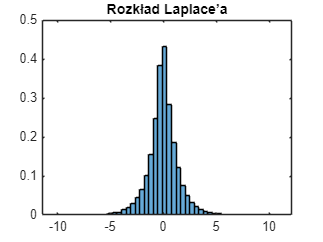


% Zadanie 4: Generator dla rozkładu Laplace’a
U = rand(1, N);
X4 = zeros(1, N);
X4(U < 0.5) = log(2 * U(U < 0.5));
X4(U >= 0.5) = -log(2 * (1 - U(U >= 0.5)));
figure(4);
histogram(X4, 50, 'Normalization', 'pdf');
title('Rozkład Laplace’a');


% Zadanie 5: Analiza metody odwracania dystrybuanty
% 
% Zalety metody odwracania dystrybuanty:
% - Prosta implementacja, wystarczy znać dystrybuantę i umieć ją odwrócić.
% - Dokładność - nie wprowadza błędów aproksymacji.
% - Uniwersalność dla ciągłych rozkładów, jeśli można znaleźć F^{-1}(u).
% 
% Wady metody odwracania dystrybuanty:
% - Nie zawsze można znaleźć F^{-1}(u) analitycznie (np. rozkład normalny).
% - Może być wolniejsza niż inne metody, jeśli F^{-1}(u) wymaga kosztownych obliczeń.
% - Nie działa dobrze dla rozkładów dyskretnych, lepiej użyć metody inwersji dla skumulowanych prawdopodobieństw.
% 
% Czy niedoskonałości generatorów jednostajnych wpływają na wyniki?
% - Tak, jeśli generator U(0,1) ma krótki okres, nierównomierny rozkład lub korelacje, błędy te przeniosą się na wynikowe rozkłady.
% 
% Kiedy metoda odwracania dystrybuanty jest korzystna, a kiedy problematyczna?
% - Korzystna: gdy można łatwo znaleźć odwrotną dystrybuantę i wymagamy dokładnych wyników.
% - Problem: gdy odwrócenie F(x) jest trudne lub obliczeniowo kosztowne.
% - Dyskretne rozkłady: metoda może być nieefektywna, lepiej stosować inne techniki.
% 
% Podsumowanie:
% Metoda odwracania dystrybuanty jest efektywna dla wielu rozkładów, ale jej skuteczność zależy od możliwości analitycznego odwrócenia dystrybuanty oraz jakości generatora U(0,1).
